# Identify the thermodynamically flux consistent subset of a model

## **Author: Ronan Fleming, **School of Medicine, University of Galway

## INTRODUCTION

The largest set of thermodynamically flux consistent reactions is defined by the cardinality optimisation problem [1]


$$\max\limits_{z,w,y} \;\Vert z\Vert_{0}+\Vert w\Vert_{0}\\
\text{s.t.}  \;Nz+Bw=0,
\\
 l\le\left[\begin{array}{c}
z\\
w
\end{array}\right]\le u,\\
 z_{j}>0\Rightarrow N_{j}^{T}y<0,\;\forall j\in1\ldots n,\\
 z_{j}<0\Rightarrow N_{j}^{T}y>0,\;\forall j\in1\ldots n,

$$


where  $z$ is an internal reaction flux vector,  $w$  is an external reaction flux vector and  $y$  may be interpreted as a vector proportional to the chemical potentials of each metabolite [2]. As with flux consistency, typically all reactions in a network do not simultaneously admit a non-zero thermodynamically consistent flux so the largest set of reactions in a network that admit a thermodynamically consistent flux is the amalgamation of a set of thermodynamically flux consistent vectors. The last two constraints above are a relaxation of the chemical thermodynamic constraint $\textrm{sign}(z_{j})=-\textrm{sign}(N_{j}^{T}y) \text{ since } z_{j}=0 \text{ does not imply, nor is implied by } N_{j}^{T}y=0$. However, they are sufficient to identify a thermodynamically flux consistent subnetwork because any internal reaction with zero flux in all thermodynamically flux consistent vectors is considered thermodynamically flux inconsistent. The function `findFluxConsistentSubset` approximately identifies the largest subset of a model that is thermodynamically consistent, i.e., each reaction admits at least one nonzero flux in a thermodynamically feasible flux vector. The image below illustrates the concept for a toy model. See  [1] for details.

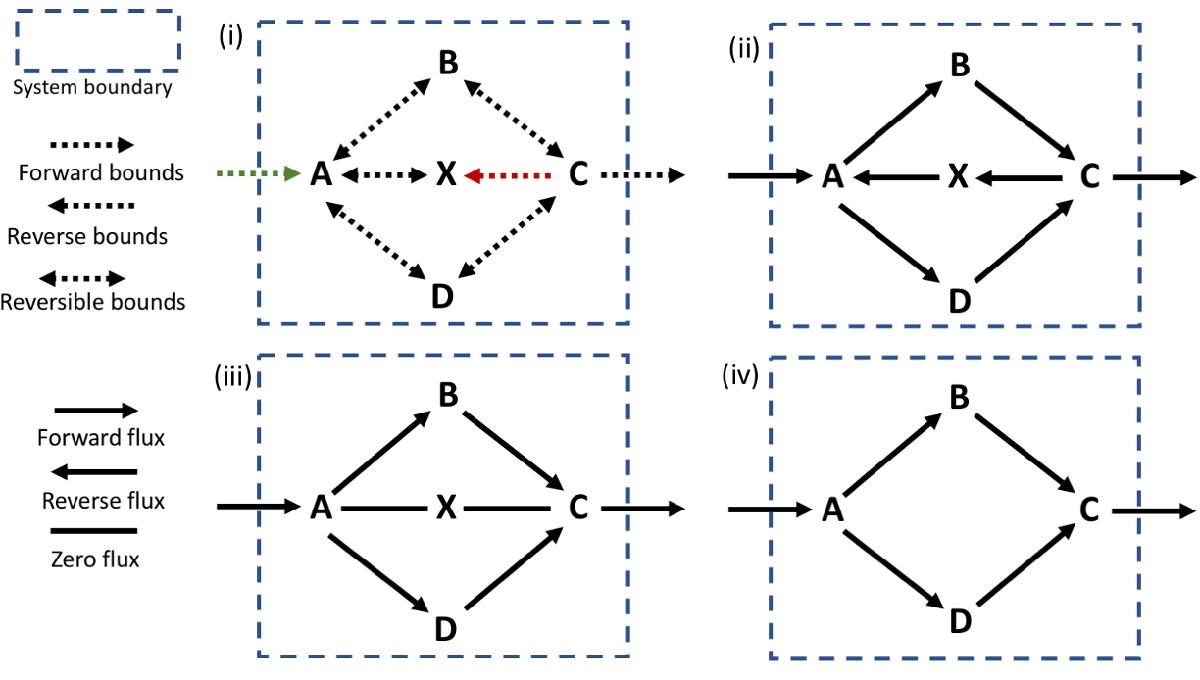

**Thermodynamic flux consistency of a toy network**. (i) Network where the lower bound on external reaction  Ø → A (green) and internal reaction C→X (red) force flux through parts of the network. (ii) Network with all reactions flux consistent. Note that this is only possible with thermodynamically inconsistent cyclic flux around a stoichiometrically balanced cycle, e.g.,  A → B → C → X → A . (iii) All internal reactions are thermodynamically consistent, but reactions C→X and X→A have zero flux, so are not thermodynamically flux consistent. (iv) A fully thermodynamically flux consistent subnetwork. Note omission of reaction C→X and X→A, which are thermodynamically flux inconsistent with the bounds given for external reaction  Ø → A (green).

## MATERIALS - EQUIPMENT SETUP

Industrial LP solver required.

## PROCEDURE

Set the directory for results

%[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','all');
[solverOK,solverInstalled]=changeCobraSolver('gurobi','all');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for LP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for MILP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for QP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > ibm_cplex (version 1210) is compatible and fully tested with MATLAB R2019a on your operating system.
 > changeCobraSolver: Solver for MIQP problems has been set to ibm_cplex.
 > changeCob

%[solverOK,solverInstalled]=changeCobraSolver('ibm_cplex','QP');

## Load model

modelToLoad='circularToy';
modelToLoad='ecoli_core';
modelToLoad='modelRecon3MitoOpen';
modelToLoad='Recon3DModel';
%modelToLoad='iDopa';

Load a model

driver_thermoModelLoad

Model loaded: Recon3DModel
lower bounds greater than zero
Internal stochiometric nullspace computed in 0.65154 seconds.


## Stoichiometric consistency

if ~isfield(model,'SConsistentRxnBool')  || ~isfield(model,'SConsistentMetBool')
    massBalanceCheck=0;
    %massBalanceCheck=1;
    printLevel=2;
    [SConsistentMetBool, SConsistentRxnBool, SInConsistentMetBool, SInConsistentRxnBool, unknownSConsistencyMetBool, unknownSConsistencyRxnBool, model,stoichConsistModel]...
        = findStoichConsistentSubset(model, massBalanceCheck, printLevel);
else
    %Extract stoich consistent submodel
    if any(~model.SConsistentMetBool)
        rxnRemoveMethod='inclusive';%maintains stoichiometric consistency
        [stoichConsistModel, rxnRemoveList] = removeMetabolites(model, model.mets(~model.SConsistentMetBool),rxnRemoveMethod);
        SConsistentRxnBool2=~ismember(model.rxns,rxnRemoveList);
        if ~all(model.SConsistentRxnBool==SConsistentRxnBool2)
            error('inconsistent reaction removal')
        end
        try
            stoichConsistModel = removeUnusedGenes(stoichConsistModel);
        catch ME
            disp(ME.message)
        end
    else
        stoichConsistModel = model;
    end
end

[nMet,nRxn]=size(stoichConsistModel.S)

nMet =         5835


nRxn =        10600


## Flux consistency

fluxConsistentParam.method='fastcc';%can handle additional constraints
fluxConsistentParam.printLevel=1;
[~,~,~,~,stoichConsistModel]= findFluxConsistentSubset(stoichConsistModel,fluxConsistentParam);

Extract flux consistent submodel

if any(~stoichConsistModel.fluxConsistentRxnBool)
    rxnRemoveList = stoichConsistModel.rxns(~stoichConsistModel.fluxConsistentRxnBool);
    stoichFluxConsistModel = removeRxns(stoichConsistModel, rxnRemoveList,'metRemoveMethod','exclusive','ctrsRemoveMethod','inclusive');
    try
        stoichFluxConsistModel = removeUnusedGenes(stoichFluxConsistModel);
        catch ME
        disp(ME.message)
    end
else
    stoichFluxConsistModel = stoichConsistModel;
end
[nMet,nRxn]=size(stoichFluxConsistModel.S)

nMet =         5835


nRxn =        10600


## Forced reactions

forcedRxnBool = model.lb>0 | model.ub<0;
nForcedRxn = nnz(forcedRxnBool)

nForcedRxn =      0


printConstraints(model,[],[],forcedRxnBool)
model.lb(strcmp(model.rxns,'biomass_reaction'))=0;
return

## Thermodynamic consistency

%save('debug_prior_to_findThermoConsistentFluxSubset.mat')
%return
param.printLevel = 1;
param.acceptRepairedFlux=1;
param.relaxBounds=1;
[thermoFluxConsistentMetBool,thermoFluxConsistentRxnBool,stoichFluxConsistModel,stoichFluxThermoConsistModel] = findThermoConsistentFluxSubset(stoichFluxConsistModel,param);

Size of the largest flux, stoich and thermo consistent submodel

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S)

## Nullspace

Nullspace is necessary for backup check of thermodynamic consistency using thermoFlux2QNty 

[stoichFluxThermoConsistModel,rankK,nnzK,timeTaken] = internalNullspace(stoichFluxThermoConsistModel);
rankK

## Minimal thermodynamically consistent submodel

Compute the minimal thermodynamically consistent submodel

[minimalModel, modelThermoMetBool, modelThermoRxnBool] = thermoKernel(stoichFluxThermoConsistModel);
[nMet,nRxn]=size(minimalModel.S)

## Data to define a thermodynamically consistent subnetwork

Setup random data to select a random subset

param.n=200;
[rankMetConnectivity,rankMetInd,rankConnectivity] = rankMetabolicConnectivity(stoichFluxThermoConsistModel,param);

[nMet,nRxn]=size(stoichFluxThermoConsistModel.S);
rxnWeights=rand(nRxn,1)-0.5;
rxnWeights(stoichFluxThermoConsistModel.SConsistentRxnBool)=0;

coreRxnBool=rxnWeights<0.45;
removeRxnBool=rxnWeights>0.48;
rxnWeights(rxnWeights>0.4)=1;
rxnWeights(rxnWeights<-0.4)=-1;
rxnWeights(rxnWeights>=-0.4 & rxnWeights<=0.4)=0;
hist(rxnWeights)
metWeights=rand(nMet,1)-0.5;
metWeights(rankMetInd(1:200))=0;
coreMetBool=metWeights<0.45;
removeMetBool=metWeights>0.5;
metWeights(metWeights>0.4)=1;
metWeights(metWeights<-0.4)=-1;
metWeights(metWeights>=-0.4 & metWeights<=0.4)=0;
hist(metWeights)

## Remove inactive reactions and absent metabolites

param.printLevel = 1;
[solverOK,solverInstalled]=changeCobraSolver('gurobi','QP');
[thermoFluxConsistentMetBool,thermoFluxConsistentRxnBool,stoichFluxThermoConsistModel,stoichFluxThermoConsistModelRed] = findThermoConsistentFluxSubset(stoichFluxThermoConsistModel, param, removeMetBool, removeRxnBool);
[nMet,nRxn]=size(stoichFluxThermoConsistModelRed.S)

## *Acknowledgments*

Co-funded by the European Union's Horizon Europe Framework Programme (101080997)

## REFERENCES

[1] Ronan M T Fleming, Hulda S Haraldsdottir, Le Hoai Minh, Phan Tu Vuong, Thomas Hankemeier, Ines Thiele, Cardinality optimization in constraint-based modelling: application to human metabolism, *Bioinformatics*, Volume 39, Issue 9, September 2023, btad450, [https://doi.org/10.1093/bioinformatics/btad450](https://doi.org/10.1093/bioinformatics/btad450) (esp Section 2.3 Thermodynamic flux consistency testing and for implementation details Supplementary Section 1.1.4 Thermodynamic flux consistency)

[2] Fleming, R. M. T., Maes, C. M., Saunders, M. A., Ye, Y., and Palsson, B. O., "A variational principle for computing nonequilibrium fluxes and potentials in genome-scale biochemical networks", *Journal of Theoretical Biology* 292 (2012), pp. 71--77.